% clc; clearvars;

Ozone Absorption Cross Section

source: [https://www.iup.uni-bremen.de/gruppen/molspec/databases/referencespectra/o3spectra2011/index.html](https://www.iup.uni-bremen.de/gruppen/molspec/databases/referencespectra/o3spectra2011/index.html)

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 14);

% Specify range and delimiter
opts.DataLines = [74, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["x________________O3AbsorptionCrossSection____________________", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
SerdyuchenkoGorshelevVersionJuly2013_Copy = readtable("C:\Users\tely1\OneDrive\Desktop\EEJ9903\lidar_model\cross_sections\ozone\serdychenko\SerdyuchenkoGorshelevVersionJuly2013 - Copy.dat", opts);

% Convert to output type
SerdyuchenkoGorshelevVersionJuly2013_Copy = table2array(SerdyuchenkoGorshelevVersionJuly2013_Copy);

% Clear temporary variables
clear opts

% Display results
SerdyuchenkoGorshelevVersionJuly2013_Copy

SerdyuchenkoGorshelevVersionJuly2013_Copy = 1.0e+03 *

    0.2133    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000       NaN       NaN
    0.2133    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000       NaN       NaN
    0.2133    0.0000    0.0000       NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2134    0.0000    0.0000    0.0000       NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2134    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000       NaN       NaN
    0.2134    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000       NaN       NaN
    0.2134    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

lams = SerdyuchenkoGorshelevVersionJuly2013_Copy(:,1);
c = SerdyuchenkoGorshelevVersionJuly2013_Copy(:,2:12);
temps = [293 283 273 263 253 243 233 223 213 203 193];

c_m2 = c.*1e-4; % convert to square meters

dd_o3 = load(".\cross_sections\ozone\dd\o3_cross_287_299.mat");

% dd_temp = dd_o3.dsigma_temp;
% dd_o3 = dd_o3.dsigma;

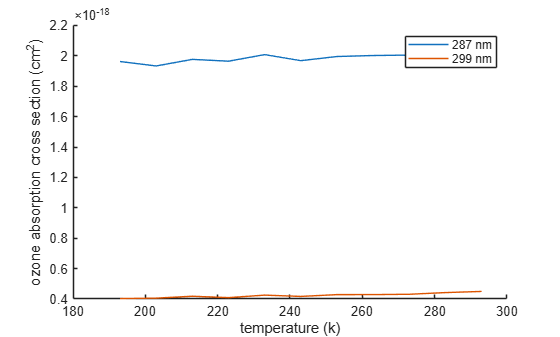

id_287 = find(lams==287.2);
id_299 = find(lams==299.1);

c_287 = c(id_287,:);
c_299 = c(id_299,:);
dc = c_287-c_299;

figure;
hold on;
plot(temps,c_287,'DisplayName','287 nm')
plot(temps,c_299,'DisplayName','299 nm')
hold off;
legend
xlabel('temperature (k)')
ylabel('ozone absorption cross section (cm^2)')

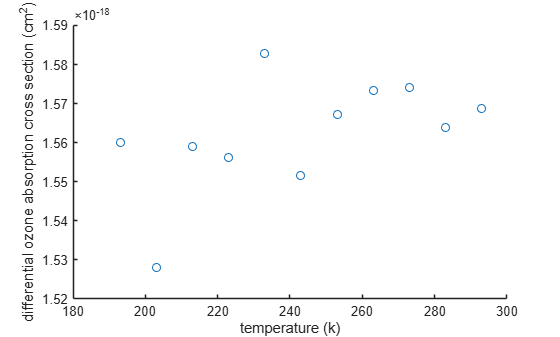


figure;
scatter(temps,dc)
xlabel('temperature (k)')
ylabel('differential ozone absorption cross section (cm^2)')

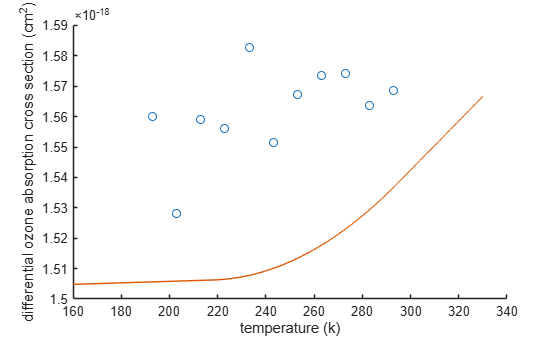

figure;
hold on
scatter(temps,dc)
plot(dd_o3.dsigma_temp, dd_o3.dsigma.*1e4)
hold off
xlabel('temperature (k)')
ylabel('differential ozone absorption cross section (cm^2)')

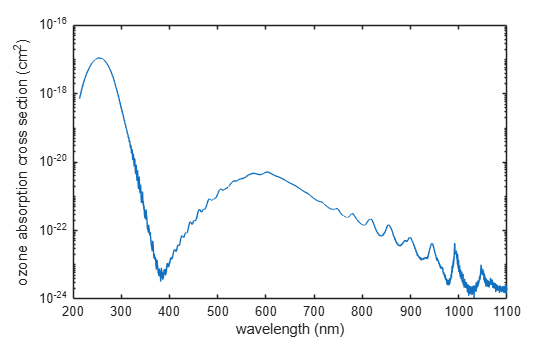

figure;
semilogy(lams,c(:,1))
xlabel('wavelength (nm)')
ylabel('ozone absorption cross section (cm^2)')

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = " ";

% Specify column names and types
opts2.VariableNames = ["lambda", "debut"];
opts2.VariableTypes = ["double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";
opts2.LeadingDelimitersRule = "ignore";

% Import the data
O3_CRS_BDM_295K_dat = readtable("C:\Users\tely1\OneDrive\Desktop\EEJ9903\lidar_model\cross_sections\ozone\bdm\O3_CRS_BDM_295K.dat.txt", opts2);

% Convert to output type
O3_CRS_BDM_295K_dat = table2array(O3_CRS_BDM_295K_dat);

% Clear temporary variables
clear opts2

% Display results
O3_CRS_BDM_295K_dat

O3_CRS_BDM_295K_dat = 1.0e+03 *

    1.9500    0.0000
    1.9501    0.0000
    1.9502    0.0000
    1.9503    0.0000
    1.9504    0.0000
    1.9505    0.0000
    1.9506    0.0000
    1.9507    0.0000
    1.9508    0.0000
    1.9509    0.0000
    1.9510    0.0000
    1.9511    0.0000
    1.9512    0.0000
    1.9513    0.0000
    1.9514    0.0000


% temps_bdm = [218 228 243 273 295];
% save("./cross_sections/ozone/bdm/bdm.mat", "O3_CRS_BDM_218K_dat", "O3_CRS_BDM_228K_dat", "O3_CRS_BDM_243K_dat", "O3_CRS_BDM_273K_dat", "O3_CRS_BDM_295K_dat","temps_bdm");

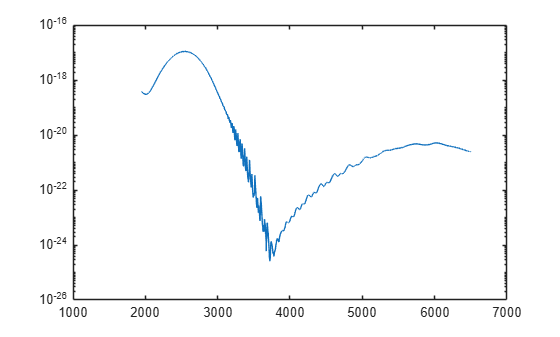

% clearvars;
load("cross_sections\ozone\bdm\bdm.mat")

figure;
semilogy(O3_CRS_BDM_218K_dat(:,1), O3_CRS_BDM_218K_dat(:,2))
xlabel('')
ylabel('')

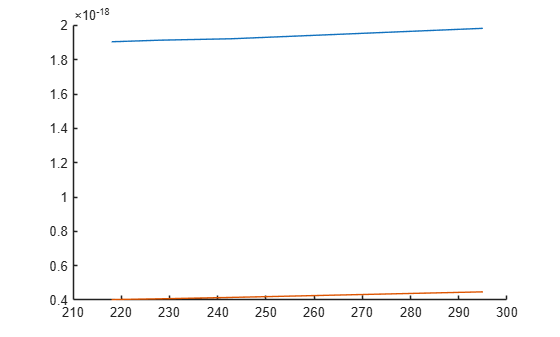

% find(O3_CRS_BDM_218K_dat(:,1)./10==287.2)
% find(O3_CRS_BDM_228K_dat(:,1)./10==287.2)
% find(O3_CRS_BDM_243K_dat(:,1)./10==287.2)
% find(O3_CRS_BDM_295K_dat(:,1)./10==287.2)
% find(O3_CRS_BDM_218K_dat(:,1)./10==299.1)
% find(O3_CRS_BDM_228K_dat(:,1)./10==299.1)
% find(O3_CRS_BDM_243K_dat(:,1)./10==299.1)
% find(O3_CRS_BDM_295K_dat(:,1)./10==299.1)
id_287 = [9271 9271 9271 9221];
id_299 = [10461 10461 10461 10411];

BDM_t = [218 228 243 295];
BDM_c287 = [O3_CRS_BDM_218K_dat(9271,2) O3_CRS_BDM_228K_dat(9271,2) O3_CRS_BDM_243K_dat(9271,2) O3_CRS_BDM_295K_dat(9221,2)];
BDM_c299 = [O3_CRS_BDM_218K_dat(10461,2) O3_CRS_BDM_228K_dat(10461,2) O3_CRS_BDM_243K_dat(10461,2) O3_CRS_BDM_295K_dat(10411,2)];

BDM_d_287_299 = BDM_c287 - BDM_c299;

save("./cross_sections/ozone/bdm/bdm_287_299.mat","BDM_t","BDM_c287","BDM_c299","BDM_d_287_299");

figure;
hold on
plot(BDM_t,BDM_c287)
plot(BDM_t,BDM_c299)
hold off

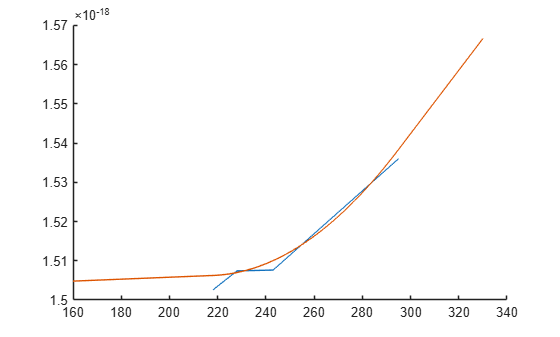

% t2 = linspace(223,293,1000);
% v = polyval(fit.coeff,t2);

figure;
hold on
plot(BDM_t,BDM_d_287_299)
plot(dd_o3.dsigma_temp,dd_o3.dsigma.*1e4)

hold off

% Set up the Import Options and import the data
opts3 = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts3.DataLines = [1, Inf];
opts3.Delimiter = " ";

% Specify column names and types
opts3.VariableNames = ["x229_9956", "x4_4645e_18", "x4_62e_18", "x4_4833e_18", "x4_5414e_18", ...
    "x4_519e_18", "Var7"];
opts3.VariableTypes = ["double", "double", "double", "double", "double", "double", ...
    "double"];

% Specify file level properties
opts3.ExtraColumnsRule = "ignore";
opts3.EmptyLineRule = "read";
opts3.ConsecutiveDelimitersRule = "join";
opts3.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts3 = setvaropts(opts3, "x229_9956", "TrimNonNumeric", true);
opts3 = setvaropts(opts3, "x229_9956", "ThousandsSeparator", ",");

% Import the data
SCIA_O3_Temp_cross_section_V4_1 = readtable("C:\Users\tely1\Downloads\SCIA_O3_Temp_cross-section_V4.1.DAT", ...
    opts3);

% Convert to output type
SCIA_O3_Temp_cross_section_V4_1 = table2array(SCIA_O3_Temp_cross_section_V4_1);

% Clear temporary variables
clear opts3

% Display results
SCIA_O3_Temp_cross_section_V4_1

SCIA_O3_Temp_cross_section_V4_1 = 1.0e+03 *

    0.2300    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2301    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2303    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2304    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2305    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2307    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2308    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2309    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2311    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2312    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2313    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2315    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2316    0.0000    0.0000    0.0000    0.0000    0.0000       NaN
    0.2317    0.0000    0.0000  

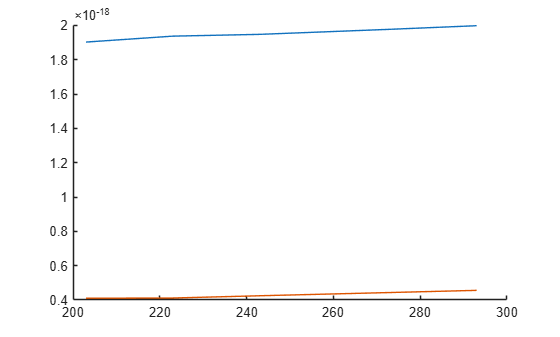

t = [203 223 243 273 293];

c287 = SCIA_O3_Temp_cross_section_V4_1(478,2:6);
c299 = SCIA_O3_Temp_cross_section_V4_1(586,2:6);

figure;
hold on
plot(t,c287)
plot(t,c299)
hold off

figure;
hold on
plot(t,c287-c299)
plot(dd_o3.dsigma_temp, dd_o3.dsigma.*1e4)
hold off